# Dynamic Model of Two Wheel Self Balancing Robot

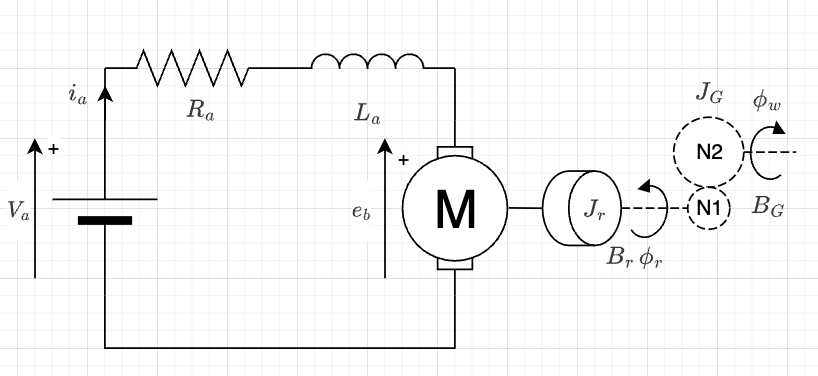

Full Transfer Function DC Motor


$$\frac{\Omega_w \left(s\right)}{V_a \left(s\right)}=\frac{K_t }{s^2 \cdot L_a R_a +\;s\left(R_a \cdot J_{\textrm{eq}} +B_{\textrm{eq}} \cdot L_a \right)+K_t {\cdot K}_e +R_a \cdot B_{\textrm{eq}} }\cdot \frac{1}{n}$$
 

Reduced order similification for small DC motros with low electical time constant 


$$\frac{\Omega_w \left(s\right)}{V_a \left(s\right)}=\frac{K_t }{\;s\left(R_a \cdot J_{\textrm{eq}} \right)+K_t {\cdot K}_e +R_a \cdot B_{\textrm{eq}} }\cdot \frac{1}{n}$$
 


$$i_a \left(t\right)=\frac{V_a \left(t\right)-K_e \dot{\phi_r } \left(t\right)}{R_a }$$



$$J_r \ddot{\phi_r } \left(t\right)+B_r \phi_r \left(t\right)+\tau_r =K_t i_a \left(t\right)$$



$$n\;\tau_r \;=\tau_w$$



$${\ddot{\phi} }_w \;\left(J_r \;n^2 +J_g \right){+\dot{\;\phi } }_w \left(\left(B_r +\frac{K_t K_e }{R_a }\right)n^2 +B_g \right)+\tau_w =\frac{nK_t V_a }{R_a }$$



$$\tau_w =-{\ddot{\phi} }_w \;J_g {\;-\dot{\;\phi } }_w \left(\frac{K_t K_e }{R_a }n^2 +B_g \right)+\frac{nK_t V_a }{R_a }$$


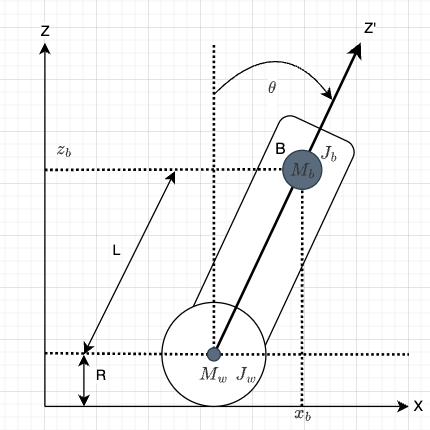

Steady State


$$\textrm{atan2}\left(-a_x ,a_z \right)$$



$$\frac{\tau_R +\tau_L }{r}=\ddot{x} \left(M_b +2M_w +2\;\frac{J_w }{r^2 }\right)+\dot{x} \left(2\frac{b_w }{r^2 }\right)+\ddot{\theta} \left(M_b L\right)$$



$$\left(\tau_R +\tau_L \right)=-\;\ddot{x} \left(M_b L\right)-\ddot{\theta} \left(M_b L^2 +J_b \right)+\theta \left(gM_b L\right)$$



$$\ddot{x} =2\frac{n}{r\alpha }\epsilon V_a -2\dot{x} \frac{\epsilon n^2 +B_g -b_w }{r^2 \alpha }-\ddot{\theta} \frac{M_b L}{\alpha }$$



$$\ddot{\theta} =-2\frac{n\epsilon }{\beta }V_a +\ddot{x} \frac{{2J}_g -rM_b L}{r\beta }+2\dot{x} \frac{\left(n^2 \epsilon +B_g \right)}{r\beta }+\theta \frac{gM_b L}{\beta }$$



$$\epsilon =\frac{K_t K_e }{R_a }$$



$$\alpha =M_b +2M_w +2\frac{J_w +J_g }{r^2 }$$



$$\beta =M_b L^2 +J_b$$


% Choi
beta = 2*m_w + 2*J_w/r2 + m_b;
alpha =  J_b*beta + 2*m_b*l2*(m_w + J_w/r2)
A22 = 2*K_e*K_t*(m_b*L*r - J_b - m_b*l2)/(R_a*r2*alpha);
A23 = m_b^2*l2*g/alpha;
A42 = 2*K_e*K_t*(r*beta - m_b*L)/(R_a*r2*alpha);
A43 = m_b^2*L*beta/alpha;

B2 = 2*K_t*(J_b + m_b*l2 - m_b*L*r)/(R_a*r*alpha);
B4 = 2*K_t*(m_b*l2 - r*beta)/(R_a*r*alpha)

clear

clear
syms N m_b L r J_b g R_a m_w J_w J_g K_t K_e real
syms x x_d x_dd theta theta_d theta_dd V_a B_g B_w

n2 = N^2; 
r2 = r^2;
l2 = L^2;
E = K_e * K_t / R_a;

% Velasquez 
% Calculating W1 and W2
W1 = 2 * ((-n2 * J_g + J_w) / r2 - m_w) - m_b + m_b^2 * l2 / (J_b + m_b * l2);
W2 = W1 * (J_b / (m_b * L) + L);

% State-space model matrices
A22 = 2 * n2 * E / (r2 * W1);
A23 = -g * m_b^2 * l2 / ((J_b + m_b * l2) * W1);
A42 = 2 * n2 * E / (r2 * W2);
A43 = -g * m_b^2 * l2 / (W2 * ((J_b + m_b * l2) + g * W1));

B2 = -2 * N * K_t / (r * R_a * W1);
B4 = -2 * N * K_t / (r * R_a * W2);

A = [0 1 0 0;  0 A22 A23  0;0 0 0 1; 0 A42 A43 0];
B = [0;B2;0;B4];

disp(A);

$$\begin{array}{l} \left[\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & -\frac{\sigma_{3}}{R_{a}\,r^{2}\,\sigma_{4}} & \frac{\sigma_{1}}{\sigma_{5}\,\sigma_{4}} & 0\\ 0 & 0 & 0 & 1\\ 0 & -\frac{\sigma_{3}}{R_{a}\,r^{2}\,\sigma_{2}\,\sigma_{4}} & \frac{\sigma_{1}}{\sigma_{2}\,\left(J_{b}+L^{2}\,m_{b}-g\,\sigma_{4}\right)\,\sigma_{4}} & 0 \end{array}\right]\\ \mathrm{where}\\ \sigma_{1}=L^{2}\,g\,{m_{b}}^{2}\\ \sigma_{2}=L+\frac{J_{b}}{L\,m_{b}}\\ \sigma_{3}=2\,K_{e}\,K_{t}\,N^{2}\\ \sigma_{4}=m_{b}+2\,m_{w}-\frac{2\,\left(J_{w}-J_{g}\,N^{2}\right)}{r^{2}}-\frac{L^{2}\,{m_{b}}^{2}}{\sigma_{5}}\\ \sigma_{5}=m_{b}\,L^{2}+J_{b} \end{array}$$

disp(B);

$$\begin{array}{l} \left[\begin{array}{c} 0\\ \frac{2\,K_{t}\,N}{R_{a}\,r\,\sigma_{1}}\\ 0\\ \frac{2\,K_{t}\,N}{R_{a}\,r\,\left(L+\frac{J_{b}}{L\,m_{b}}\right)\,\sigma_{1}} \end{array}\right]\\ \mathrm{where}\\ \sigma_{1}=m_{b}+2\,m_{w}-\frac{2\,\left(J_{w}-J_{g}\,N^{2}\right)}{r^{2}}-\frac{L^{2}\,{m_{b}}^{2}}{m_{b}\,L^{2}+J_{b}} \end{array}$$


% Numerical Values
N_val = 20; 
m_b_val = 3; 
L_val = 0.1;
r_val = 0.04825;
J_b_val = 0.0125;
g_val = 9.81;
R_a_val = 3; 
m_w_val = 0.113; 
J_w_val = 0.0001548;
J_g_val = 0.0003;
K_t_val = 0.24;
K_e_val = 0.24;
% Perform Substitution
params = [N, m_b, L, r, J_b, g, R_a, m_w, J_w, J_g, K_t, K_e];
values = [N_val, m_b_val, L_val, r_val, J_b_val, g_val, R_a_val, m_w_val, J_w_val, J_g_val, K_t_val, K_e_val];
% Define A, B, C, D matrices for state-space system
A = [0 1 0 0; 0 A22 A23 0; 0 0 0 1; 0 A42 A43 0];
B = [0;B2;0;B4];
C = [0 1 0 0; 0 0 1 0];
D = zeros(2, 1);


A_num = subs(A, params, values);
B_num = subs(B, params, values);
W1_num = subs(W1, params, values);
W2_num = subs(W2, params, values);
format shortE
% Convert to Numeric Format
A_num = double(A_num);
B_num = double(B_num);
C_num = double(C);
D_num = double(D);

disp(A_num);

            0   1.0000e+00            0            0
            0  -6.3400e+01   1.9963e-01            0
            0            0            0   1.0000e+00
            0  -4.4753e+02  -5.8665e-05            0



disp(B_num);

            0
   6.3730e-01
            0
   4.4986e+00




% Define weighting matrices for LQR
Q = diag([10, 1, 100, 1]);  % Weighting on state variables [x, ẋ, φ, φ̇]
R = 0.1;           % Weighting on control inputs (motor voltages)

% Compute the LQR gain matrix K
K = lqr(A_num, B_num, Q, R)

K =    1.0000e+01   1.5082e+01   3.2124e+01  -1.2722e+00


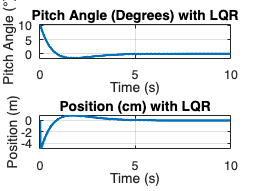

% Closed-loop system (A - B*K)
Acl = A_num - B_num * K;
sys_cl = ss(Acl, B_num, C_num, D_num);
% Simulate with correct function usage
t = 0:0.01:10;
x0 = [0; 0; deg2rad(10.15); 0];  % Initial position, velocity, pitch 
[response, t_out, x_out] = lsim(sys_cl, zeros(size(t)), t, x0);

% Ensure figure is visible
fig = figure;
hold on;

% Plot pitch angle (φ)
subplot(2,1,1);
plot(t_out, rad2deg(response(:,2)), 'LineWidth', 2);
title('Pitch Angle (Degrees) with LQR');
xlabel('Time (s)');
ylabel('Pitch Angle (°)');
grid on;

% Plot position (x)
subplot(2,1,2);
plot(t_out, response(:,1)*10^2, 'LineWidth', 2);
title('Position (cm) with LQR');
xlabel('Time (s)');
ylabel('Position (m)');
grid on; hold off;

%% DC Motor Model
clear
Jr = 3.2284E-5;   % rotor rotational inertia        [Nms^2/rad]
Jg = 3.22E-5;     % Gearbox Rotational Inertia
Bg = 0.0001;      % vicous friction           [Nms/rad]
Br = 0;

% DC Motor Manufacturuer Parameters 
IStall = 2;
TStall = 0.39;
Inoload = 0.2;
n = 20;
%Identified parameters
speedvolt_grad = 0.6594*n*2*pi; % Measumenents in RPS of output shaft

Kt = ((IStall - Inoload)/ TStall) ^-1;         % Motor Torque constant        []
Ke = (speedvolt_grad)^-1 ;        % Motor Back EMF constant speed voltage gradient      []
Ra = 2.6;         % armature resistance       [Ω]
La = 1E-6;        % armature inductance          [H]
n = 20;
Jeq = Jg + n^2*Jr;
Beq = Bg + n^2*Br;


s = tf("s"); 
motor_tf = (Kt*n^-1)/((s^2)*(La*Ra) + s*(Ra*Jeq + Beq *La) + Kt*Ke + Ra*Beq)
motor_simp_tf = (Kt*n^-1)/ (s*(Ra*Jeq) + Kt*Ke + Ra*Beq)

step(motor_simp_tf ); ylabel('rads');grid on; grid minor;  
hold on; step(motor_tf); s  hold off; legend("Simplified","Full Order");